Root Mean Squared Error on the Test Set: 8139.94


Mean Error on the Test Set: -206.48


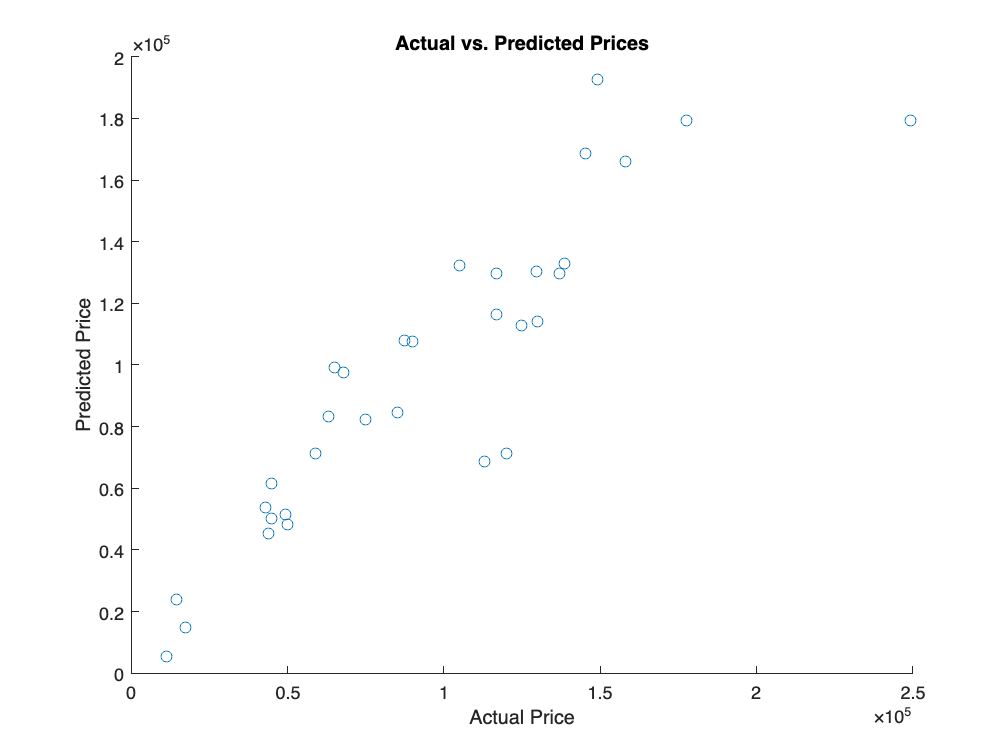

Predicted Price for the Desired Car: 39923 EUR


% Load the data 
data = CarsDataAfter;

% Feature scaling
data.YearOfFabrication = zscore(data.YearOfFabrication);
data.Kilometres = zscore(data.Kilometres);

while true
    % User input for the brand and model of the car
    userBrand = input('Enter the brand: ', 's');
    userModel = input('Enter the model: ', 's');

    % Convert the user input to lowercase for case-insensitive comparison
    userBrand = lower(userBrand);
    userModel = lower(userModel);

    % Convert categorical variables to strings for comparison
    dataBrandAsString = cellstr(data.Brand);
    dataModelAsString = cellstr(data.Model);

    % Compare the converted data with the user input
    rowsWithSameBrand = strcmpi(dataBrandAsString, userBrand);
    rowsWithSameModel = strcmpi(dataModelAsString, userModel);

    % Find rows where both brand and model match the user input
    searchRows = rowsWithSameBrand & rowsWithSameModel;

    dataFiltered = data(searchRows, :);

    if ~isempty(dataFiltered)
        % 'PriceEuro' is the target variable
        features = dataFiltered(:, {'Brand', 'Model', 'YearOfFabrication', 'Kilometres'});
        target = dataFiltered.PriceEuro;

        % Convert categorical variables to dummy variables
        categoricalVariables = {'Brand', 'Model'};

        for i = 1:length(categoricalVariables)
            category = categorical(features.(categoricalVariables{i}));
            dummyVariables = dummyvar(category);

            nonZeroColumns = any(dummyVariables ~= 0, 1);
            dummyVariables = dummyVariables(:, nonZeroColumns);

            dummyTable = array2table(dummyVariables, 'VariableNames', strcat(categoricalVariables{i}, '_', string(1:size(dummyVariables, 2))));
            features = [features, dummyTable];
        end

        % Remove the original categorical variables
        features(:, categoricalVariables) = [];

        % Add quadratic terms for 'YearOfFabrication' and 'Kilometres'
        features.YearOfFabrication2 = features.YearOfFabrication.^2;
        features.Kilometres2 = features.Kilometres.^2;

        % Convert 'YearOfFabrication' and 'Kilometres' to doubles
        features.YearOfFabrication = double(features.YearOfFabrication);
        features.Kilometres = double(features.Kilometres);

        % Convert 'YearOfFabrication2' and 'Kilometres2' to doubles
        features.YearOfFabrication2 = double(features.YearOfFabrication2);
        features.Kilometres2 = double(features.Kilometres2);

        % Convert all variables to numeric arrays
        features = [table2array(features)];

        % Split the data into training and testing sets
        cv = cvpartition(size(features, 1), 'HoldOut', 0.2);
        idxTrain = training(cv);
        idxTest = test(cv);

        % Create training and testing sets
        XTrain = features(idxTrain, :);
        YTrain = target(idxTrain);
        XTest = features(idxTest, :);
        YTest = target(idxTest);

        % Train the machine learning model with elastic net regularization
        mdl = fitrnet(XTrain, YTrain, 'Standardize', true, 'Lambda', 0.1);

        % Evaluate the model on the test set
        YTestPredicted = predict(mdl, XTest);

        % Assess the model performance
        rmse = sqrt(mean((YTestPredicted - YTest).^2));
        fprintf('Root Mean Squared Error on the Test Set: %.2f\n', rmse);
        % Calculate the mean error
        meanError = mean(YTestPredicted - YTest);
        fprintf('Mean Error on the Test Set: %.2f\n', meanError);


        % Visualize actual vs. predicted values
        figure;
        scatter(YTest, YTestPredicted);
        xlabel('Actual Price');
        ylabel('Predicted Price');
        title('Actual vs. Predicted Prices');

        % User input for the year and km of the car
        while true
            userYear = input('Enter the year of fabrication: ');
            % Check if userYear is within a valid range
            if userYear >= 2000 && userYear <= 2023
                break;
            else
                disp('Invalid year. Please enter a year between 2000 and 2023.');
            end
        end

        while true
            userKilometers = input('Enter the kilometers: ');
            % Check if userKilometers is within a valid range
            if userKilometers >= 0
                break;
            else
                disp('The number of kilometers cannot be negative. Try entering a valid number.');
            end
        end

        % Feature scaling for user input
        userYear = zscore(userYear);
        userKilometers = zscore(userKilometers);

        % Add quadratic terms for user input
        userYear2 = userYear^2;
        userKilometers2 = userKilometers^2;

        % Convert input into categorical
        userBrandCat = categorical(cellstr(userBrand));
        userModelCat = categorical(cellstr(userModel));

        % Convert categorical variables to dummy variables
        dummyBrand = dummyvar(double(userBrandCat));
        dummyModel = dummyvar(double(userModelCat));

        % Remove the original categorical variables
        userInput(:, {'Brand', 'Model'}) = [];

        % Create a table with a single row for user input
        userInput = table(userYear, userKilometers, userYear2, userKilometers2, dummyBrand, dummyModel, 'VariableNames', {'YearOfFabrication', 'Kilometres', 'YearOfFabrication2', 'Kilometres2', 'Brand', 'Model'});

        % Predict the price for the user's input
        userPrediction = predict(mdl, table2array(userInput));
        userPrediction = round(userPrediction);
        fprintf('Predicted Price for the Desired Car: %d EUR\n', userPrediction);

        break;
    else
        disp('No matching data found. Please try again.');
    end
end